figure;
EEG.chanlocs = readlocs('channelLocations.locs')

readlocs(): 'loc' format assumed from file extension


EEG = struct with fields:
    chanlocs: [1×13 struct]


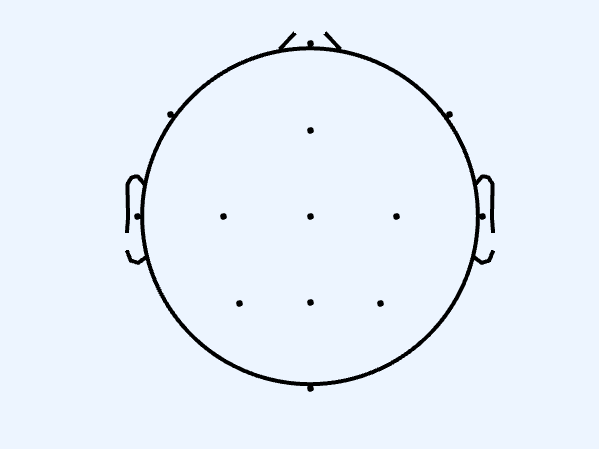

topoplot([], EEG.chanlocs);

load("data_3.mat")

% Calculate spectrogram
window_size = 30 * Fs;
overlap_size = 29 * Fs;
freq_range = 0.1:0.1:32;

% Calculate spectrograms for all 13 signals
S = cell(13,1);
F = cell(13,1);
T = cell(13,1);
P = cell(13,1);
for i = 1:13
    [S{i}, F{i}, T{i}, P{i}] = spectrogram(signal(i,:), window_size, overlap_size, freq_range, Fs);
end

% Calculate total power for all 13 signals
total_power = cell(13, 1);
for i = 1:13
    total_power{i} = sum(P{i}, 1);
end

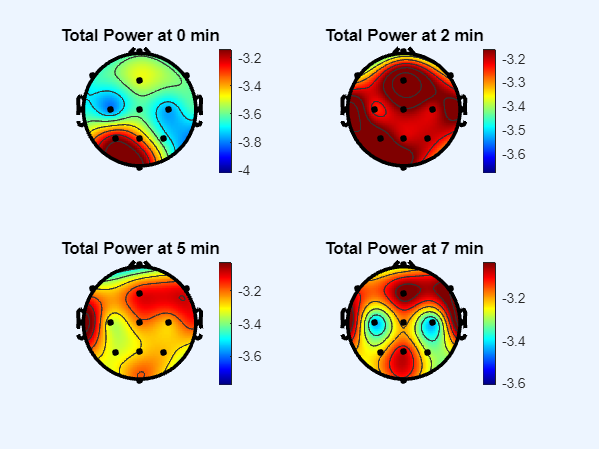

% Plot the total power maps using topoplot
t_points = [0 120 300 420];
% [idx, loc] = ismember(T{1}, t_points);
% t_idx = find(idx);

figure;
for i = 1:length(t_points)
    t_power_tmp = cellfun(@(x) x(t_points(i) + 1), total_power);
    subplot(2,2,i);
    topoplot(log10(t_power_tmp), EEG.chanlocs, 'maplimits', 'maxmin');
    colorbar;
    title(['Total Power at ' num2str(t_points(i)/60) ' min']);
end

% Sum the four frontal electrodes into a single signal
P_front = P{[1 3 4 10]};
frontal_signal = sum(P_front, 1);

% Sum the four rear electrodes into a single signal
P_rear = P{[7 9 12 13]};
rear_signal = sum(P_rear, 1);

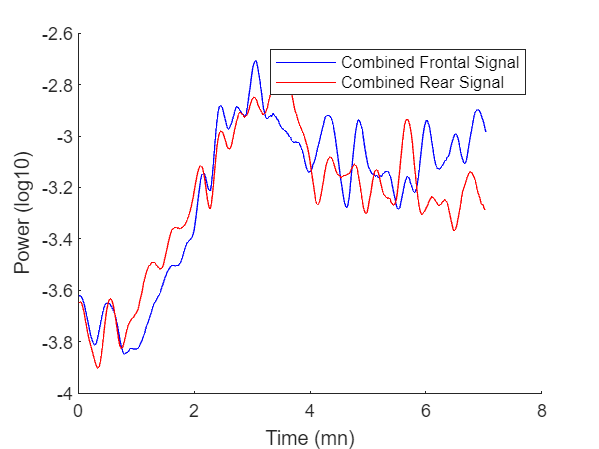

figure;
% subplot(2,1,1);
hold on;
plot((1:length(frontal_signal))/60, log10(frontal_signal), 'b');
plot((1:length(rear_signal))/60, log10(rear_signal), 'r');
xlabel('Time (mn)');
ylabel('Power (log10)');
legend('Frontal Signal', 'Rear Signal');

delta_rel_pow = cell(13,1);
alpha_rel_pow = cell(13,1);

for i = 1:13
    F_i = F{i};
    P_i = P{i};
    total_power_i = total_power{i};

    delta_idx = find(F_i>=1 & F_i<4);
    alpha_idx = find(F_i>=8 & F_i<12);

    delta_rel_pow{i} = sum(P_i(delta_idx,:), 1) ./ total_power_i;
    alpha_rel_pow{i} = sum(P_i(alpha_idx,:), 1) ./ total_power_i;
end

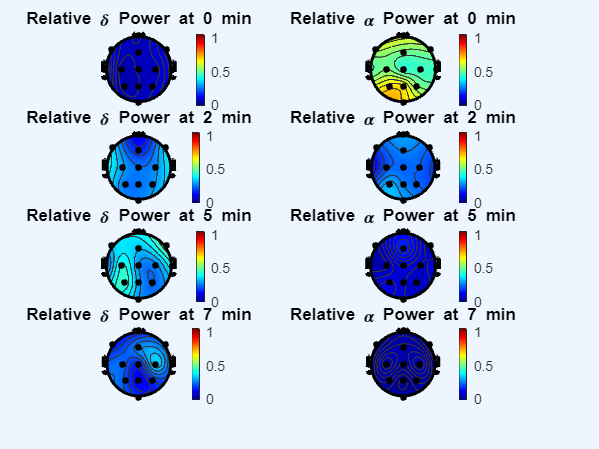

figure;
for i = 1:length(t_points)
    delta = cellfun(@(x) x(t_points(i) + 1), delta_rel_pow);
    alpha = cellfun(@(x) x(t_points(i) + 1), alpha_rel_pow);

    subplot(4,2,2*i-1);
    topoplot(delta, EEG.chanlocs, 'maplimits', [0, 1]);
    colorbar;
    title(['Relative \delta Power at ' num2str(t_points(i)/60) ' min']);

    subplot(4,2,2*i);
    topoplot(alpha, EEG.chanlocs, 'maplimits', [0, 1]);
    colorbar;
    title(['Relative \alpha Power at ' num2str(t_points(i)/60) ' min']);

end